# Power-Split Hybrid Electric Vehicle Model with Speed Tracking

Copyright 2021 The MathWorks, Inc.

## Open the Model

mdl = "PowerSplitHEV_SpeedTracking";
if not(bdIsLoaded(mdl)), open_system(mdl); end

% Run setup script
PowerSplitHEV_SpeedTracking_setup

## Load Inputs

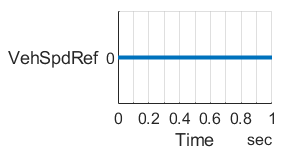

% Vehicle longitudinal velocity reference
fig = figure;
[inputSignals_DrivingPattern, inputBus_DrivingPattern, t_end] = ...
  DrivingPatternBasic_inputs( "PlotParent",fig, "InputPattern","all_zero" );

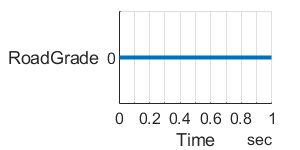

% Road grade
fig = figure;
[inputSignals_RoadGrade, inputBus_RoadGrade] = ...
  DriverAndEnvironment_road_grade_pattern( "PlotParent",fig, "InputPattern", "all_zero" );
fig.Position(3:4) = [200 100];  % width height

## Run Simulation

% Set initial conditions
initial.driverBrakeForce_N = 8000;
initial.driverBrakeOn_tf = true;
initial.driverHVBattSOC_pct = 96;

initial.vehicleSpeed_kph = 0;
initial.motorGenerator2_speed_rpm = 0;
initial.motorGenerator1_speed_rpm = 0;
initial.engine_speed_rpm = 0;
initial.engine_torque_Nm = 0;

% Override block parameters
drivingPattern.useFromWorkspace_tf = true;

% Set Simulation Input
in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('StopTime',num2str(t_end));

% Run simulation
out = sim(in);

## Visualize Simulation Result

Vehicle

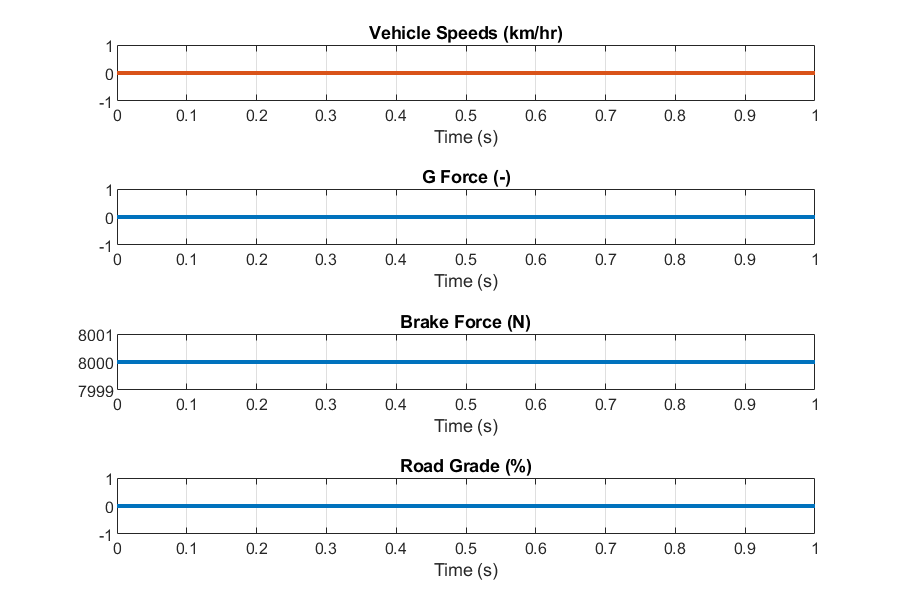

fig = figure;
fig.Position(3:4) = [600 400];  % width height
PowerSplitHEV_SpeedTracking_plot_result_vehicle( "Dataset",out.logsout, "PlotParent",fig );

High Voltage Battery

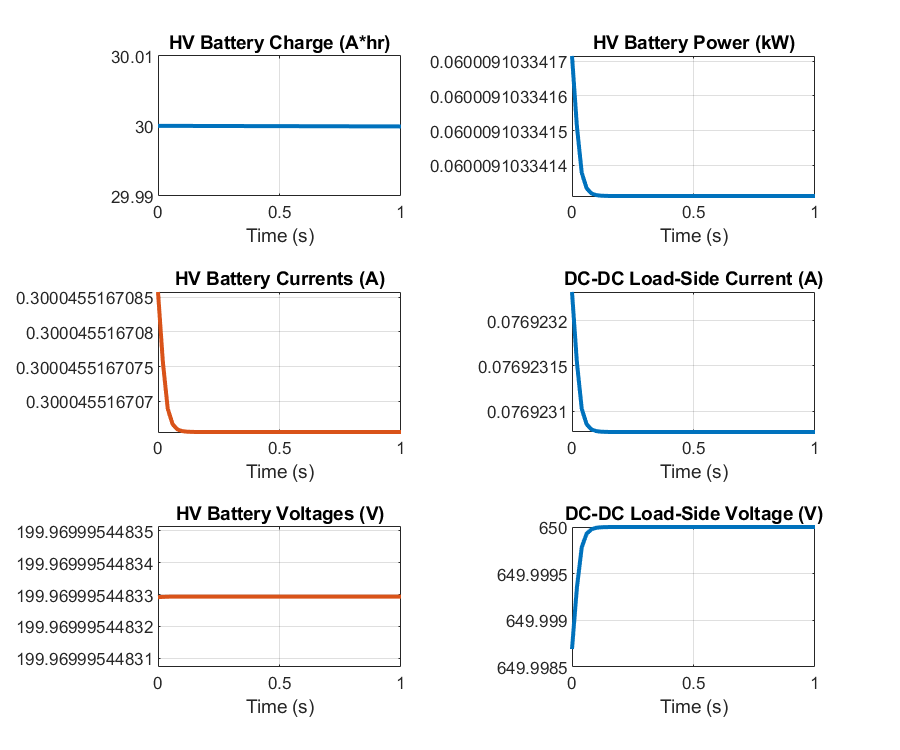

fig = figure;
fig.Position(3:4) = [600 500];  % width height
PowerSplitHEV_SpeedTracking_plot_result_hvbattery( "Dataset",out.logsout, "PlotParent",fig );

Power-Split Drive Unit

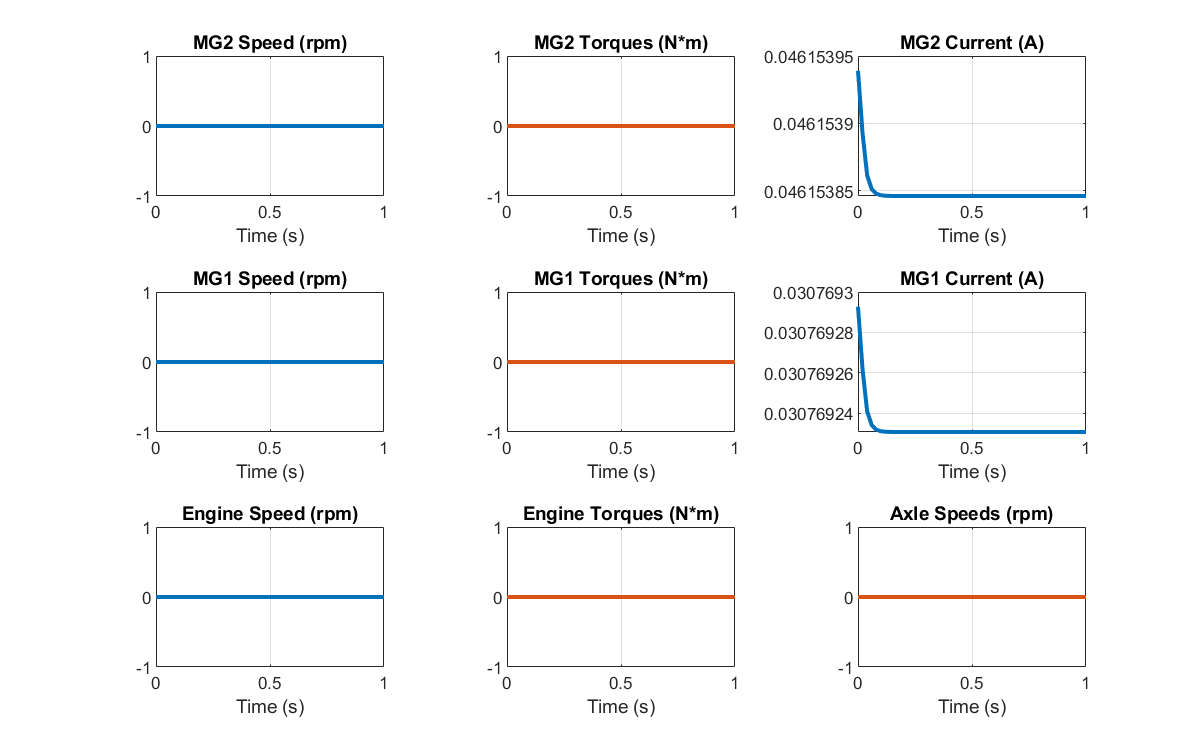

fig = figure;
fig.Position(3:4) = [800 500];  % width height
PowerSplitHEV_SpeedTracking_plot_result_powersplit( "Dataset",out.logsout, "PlotParent",fig );